# Star-shaped Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a Y-shaped graph, which is defined using the *star* template.

## Set up the graph structure and coordinates of the problem

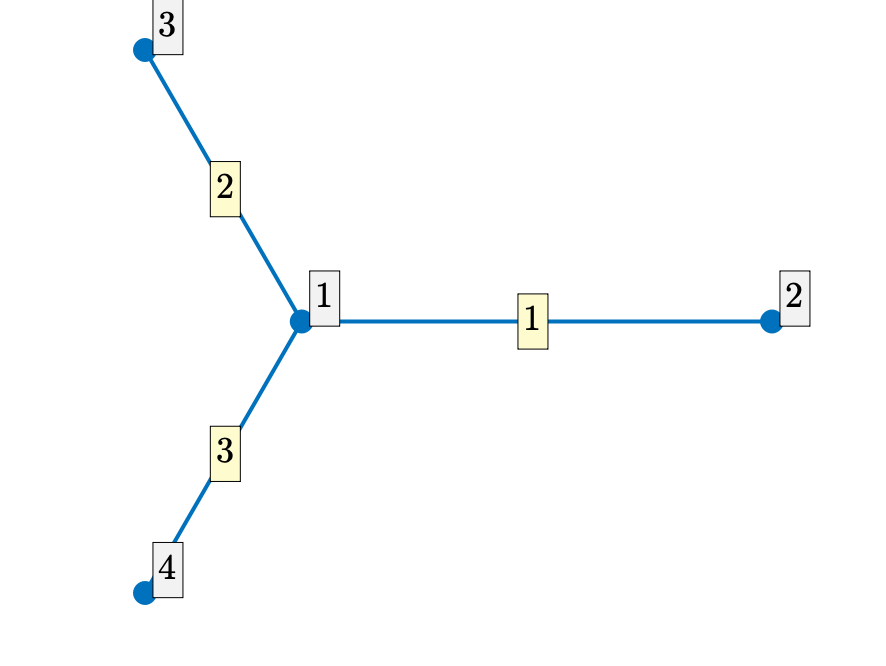

LVec=[1.5 1 1]; nX = 40; rC = [0 0 nan nan];
Phi = quantumGraphFromTemplate('star','LVec',LVec,'nX',nX,'robinCoeff',rC);
Phi.plot('layout')

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes calculated as positive and sometimes as negative and this messes up the sorting.

[V,lambda]=eigs(Phi,10);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

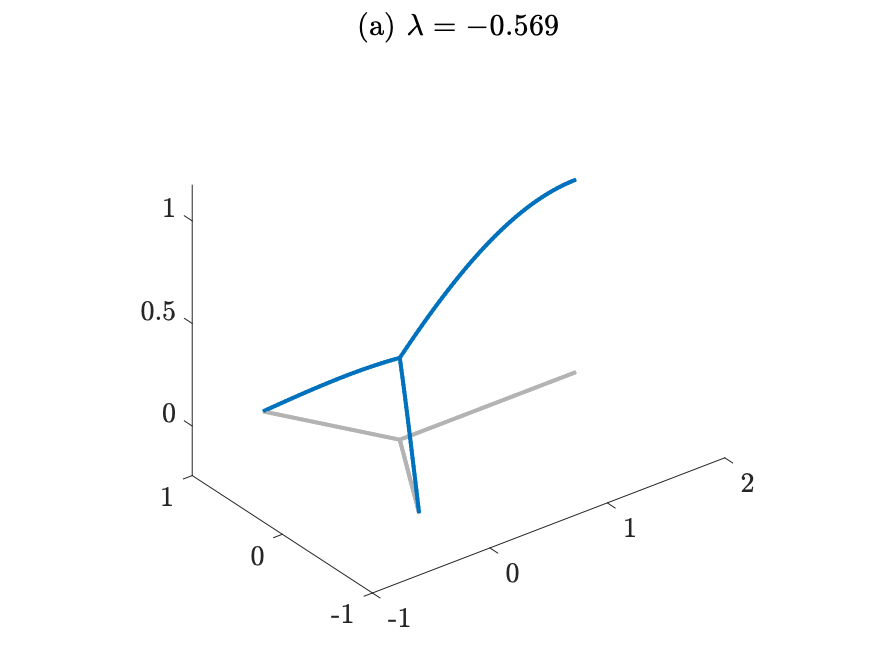

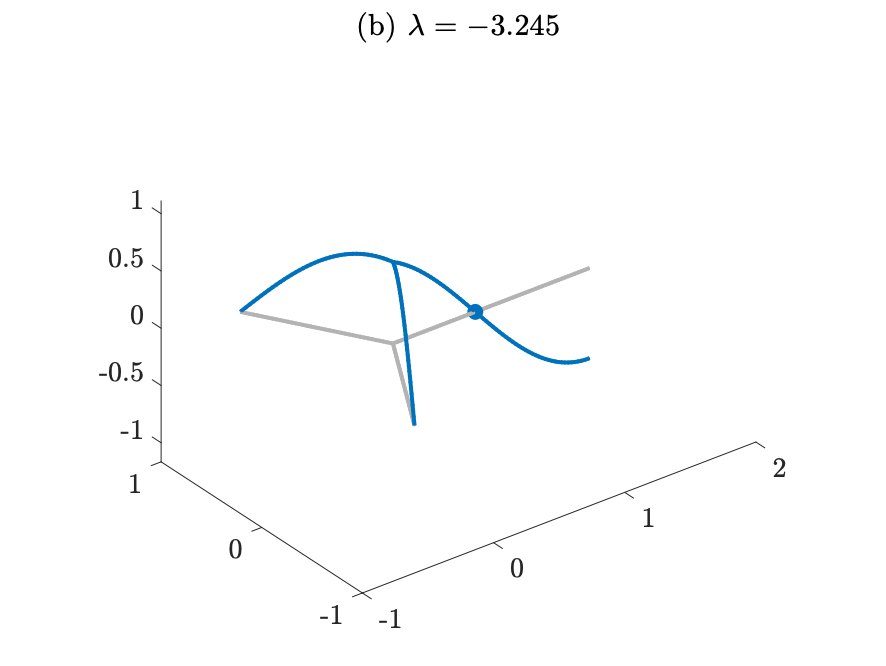

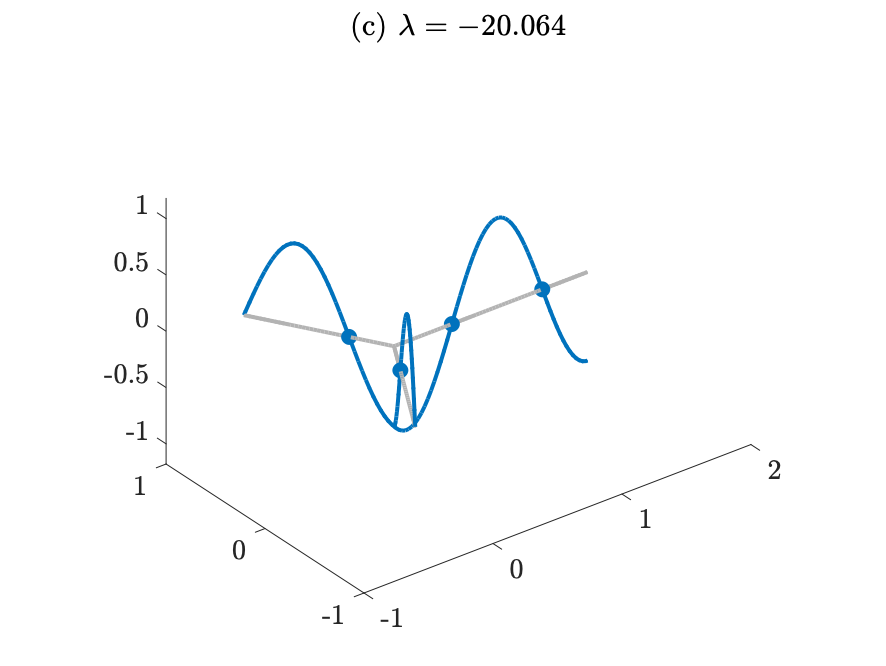

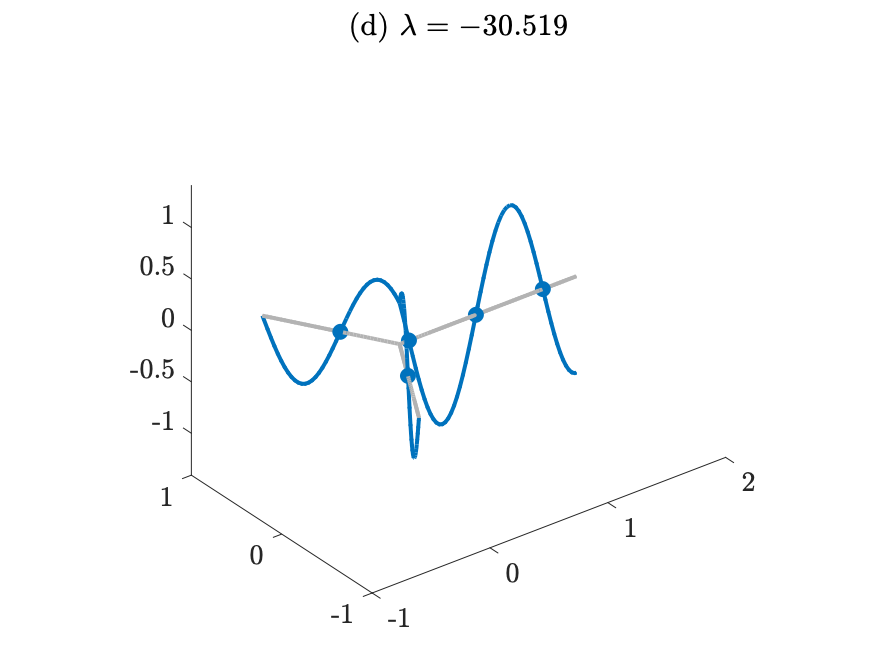

for k=1:nToPlot
    figure
    Phi.plot(V(:,singles(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

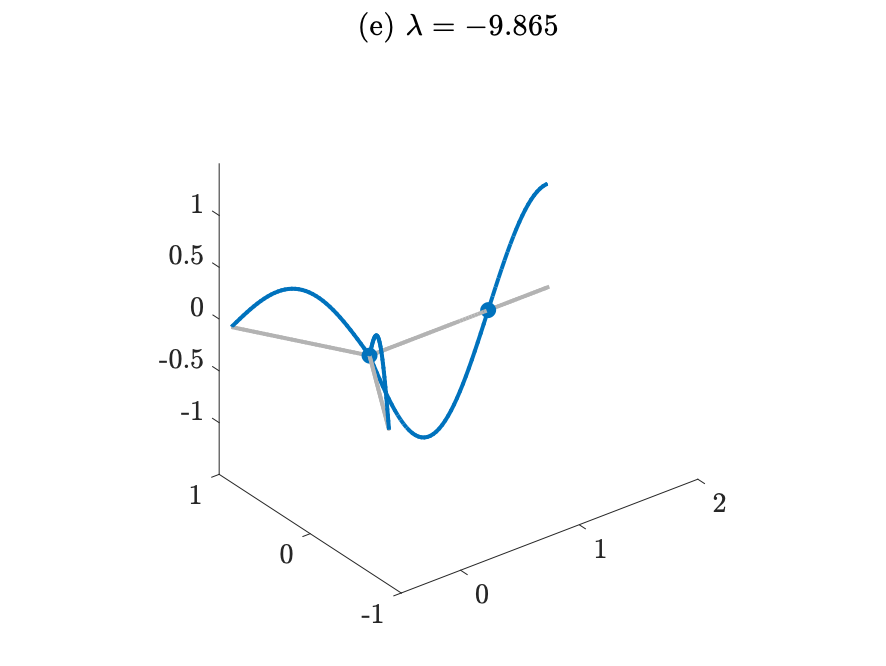

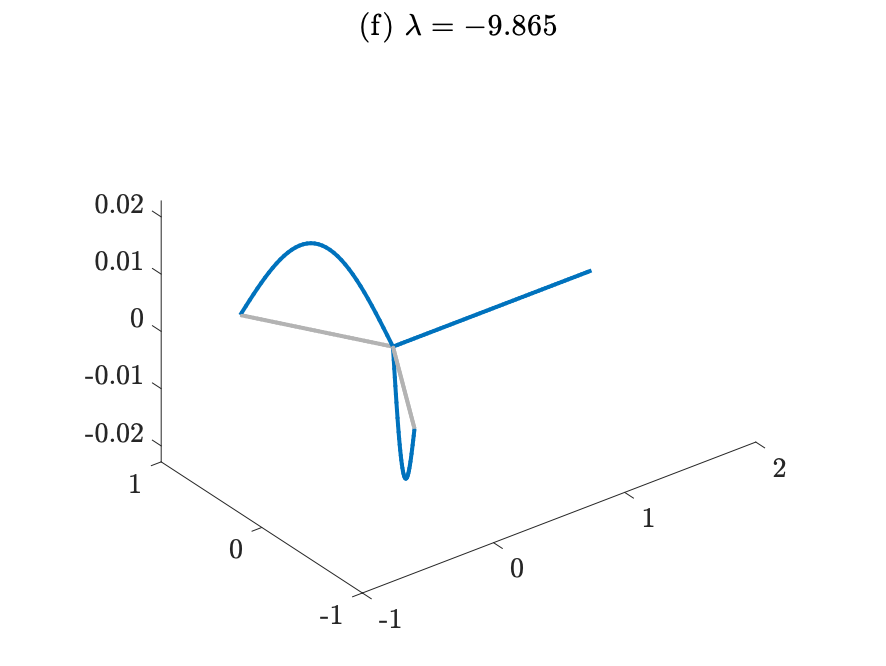

if ~isempty(doubles)
    
    for k=1:min(nToPlot/2,length(doubles))
        v=starResolveDoubles(V,doubles(k),Phi);
        figure
        Phi.plot(v{1})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k-1), lambda(doubles(k))));
        figure
        Phi.plot(v{2})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k), lambda(doubles(k))));
    end
end